# Eye

## Cone Photoreceptor Fundamentals

Cone sensitivity fundamental derived from photocurrent recordings of excised monkey retina


$$\log \left(S\right)=\sum_{n=0}^6 a_n {\left\lbrack \log \left(\frac{1}{\lambda }\frac{\lambda_m }{\lambda_r }\right)\right\rbrack }^n$$


Coefficients $a_0$ to $a_6$ are -5.2734, -87.403, 1228.4, -3344.3, -5070.3, 30881, and -31067 respectively. Red wavelength $\lambda_r=561nm$ and $\lambda_m$ is set to 561, 531, and 430 nm respectively

`Baylor, B. Y. D. A., Nunn, B. J., & Schnapft, J. L. (1987). Spectral Sensitivity of Cones of the Monkey. ``Journal of Physiology``, ``390``, 145–160. https://doi.org/10.1113/jphysiol.1987.sp016691`

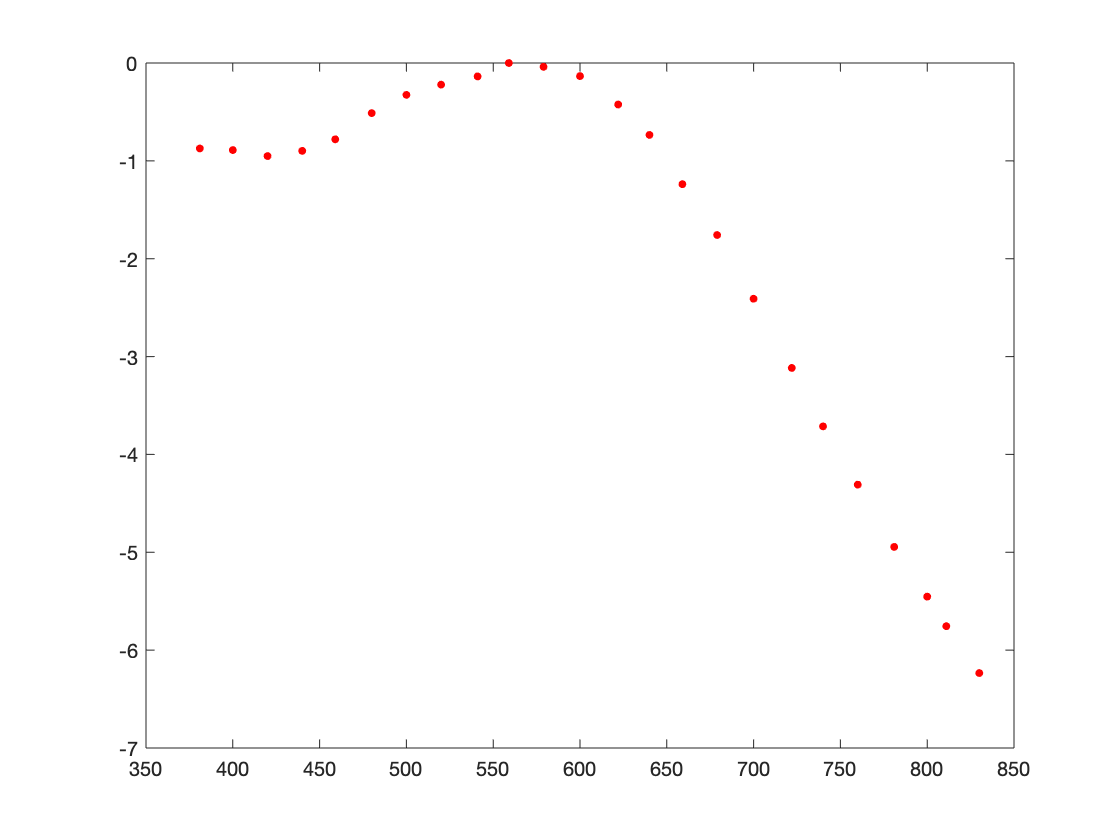

clearvars
red_table = readtable("coneSensitivity_Baylor.xlsx", "Sheet", "Red", "PreserveVariableNames", true);
green_table = readtable("coneSensitivity_Baylor.xlsx", "Sheet", "Green", "PreserveVariableNames", true);
blue_table = readtable("coneSensitivity_Baylor.xlsx", "Sheet", "Blue", "PreserveVariableNames", true);

plot(red_table.wave, red_table.logS, "r.", "MarkerSize", 10)